clc; close all; clear drawArm;clear;
addpath('inc\')
load("data\system_parameters.mat");
load("data\circle_points.mat")

dt = 0.1;

## Double number of knots

o4 = [point(:,1)';
    point(:,5)';
    point(:,10)';
    point(:,15)';
    point(:,20)';
    point(:,25)';
    point(:,30)';
    point(:,34)';
    point(:,37)'];

v4 = [0 0 0;
    0 -19e-3 19e-3;
    0 -27e-3 0;
    0 -19e-3 -19e-3;
    0  0 -27e-3;
    0 19e-3 -19e-3;
    0 27e-3 0;
    0 19e-3 19e-3;
    0 0 0];


index = 1;
for k = 1:8
    tA = 0;
    tB = 0.7;
    pointA = o4(k,:)';
    pointB = o4(k+1,:)';
    qA = invKin([0 0 0],pointA,"ElbowUp",p);
    qB = invKin([0 0 0],pointB,"ElbowUp",p);
    TA = fwdKin(qA,p);
    TB = fwdKin(qB,p);
    JA = jac(TA.T40(1:3,4),TA);
    JB = jac(TB.T40(1:3,4),TB);
    
    v4A = v4(k,:)';
    v4A_4 = TA.T40(1:3,1:3)\v4A; % tip velocity in tip frame
    w4A = [0;0;-v4A_4(3)/norm(TA.T40(1:2,4))];
    
    v4B = v4(k+1,:)';
    v4B_4 = TB.T40(1:3,1:3)\v4B; % tip velocity in tip frame
    w4B = [0;0;-v4B_4(3)/norm(TB.T40(1:2,4))];
    
    XiA = [v4A;w4A];
    XiB = [v4B;w4B];
    
    qA_d = invVel(JA,XiA);
    qB_d = invVel(JB,XiB);
    
    for i = 1:4
        polAB(i,:)= trajPol([qA(i) qA_d(i) 0],[qB(i) qB_d(i) 0],tA,tB);
    end   
    
    if(k == 1)
        for t = tA:dt:tB
            qAB_10(:,index) = polAB*[1 t t^2 t^3 t^4 t^5]';
            qAB_10_d(:,index) = polAB*[0 1 2*t 3*t^2 4*t^3 5*t^4]';
            qAB_10_dd(:,index) = polAB*[0 0 2 6*t 12*t^2 20*t^3]';
            index = index+1;
        end
    else
    
        for t = tA+dt:dt:tB
            qAB_10(:,index) = polAB*[1 t t^2 t^3 t^4 t^5]';
            qAB_10_d(:,index) = polAB*[0 1 2*t 3*t^2 4*t^3 5*t^4]';
            qAB_10_dd(:,index) = polAB*[0 0 2 6*t 12*t^2 20*t^3]';
            index = index+1;
        end
    end
end
save('data\trajectory_jointSpace_10points','qAB_10','qAB_10_d','qAB_10_dd')



## Tip Position

load("data\trajectory_jointSpace_5points.mat")
o4_5 = zeros(3,length(qAB_5));
for i = 1:length(qAB_5)
    o4_5(:,i) = fwdKin(qAB_5(:,i),p).T40(1:3,4);
end

o4_10 = zeros(3,length(qAB_10));
for i = 1:length(qAB_10)
    o4_10(:,i) = fwdKin(qAB_10(:,i),p).T40(1:3,4);
end

## Plotting

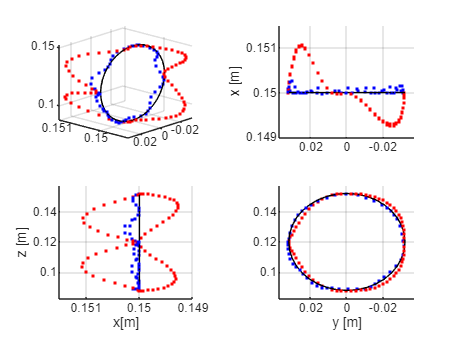

figure;
tiledlayout(2,2)
ax1 = nexttile;
hold on
plot3(o4_5(1,:),o4_5(2,:),o4_5(3,:),'.',Color='r')
plot3(o4_10(1,:),o4_10(2,:),o4_10(3,:),'.',Color='b')
plot3(point(1,:),point(2,:),point(3,:),'k')
view([222.740 19.787])
% axis square;
grid on
ax2 = nexttile;
hold on
plot3(o4_5(1,:),o4_5(2,:),o4_5(3,:),'.',Color='r')
plot3(o4_10(1,:),o4_10(2,:),o4_10(3,:),'.',Color='b')
plot3(point(1,:),point(2,:),point(3,:),'k')
view([-90 90]);
grid on
ax3 = nexttile;
hold on
plot3(o4_5(1,:),o4_5(2,:),o4_5(3,:),'.',Color='r')
plot3(o4_10(1,:),o4_10(2,:),o4_10(3,:),'.',Color='b')
plot3(point(1,:),point(2,:),point(3,:),'k')
view([-180 0]);
grid on
ax4 = nexttile;
hold on
plot3(o4_5(1,:),o4_5(2,:),o4_5(3,:),'.',Color='r')
plot3(o4_10(1,:),o4_10(2,:),o4_10(3,:),'.',Color='b')
plot3(point(1,:),point(2,:),point(3,:),'k')
% plot(o4(2,:),o4(3,:),'.',Color='r')
% plot(point(2,:),point(3,:),'k')
view([-90 0]);
grid on
% axis equal
linkaxes([ax2 ax3 ax4],'xyz')
ax4.ZLim = [0.083 0.157];
ax4.YLim = [-0.037 0.037];

nexttile(2)
xlabel("x [m]")
nexttile(3)
xlabel("x[m]")
zlabel("z [m]")
nexttile(4)
ylabel("y [m]")

## Drawing for Testing

h = figure();
plot3(point(1,:),point(2,:),point(3,:))
i = 1;
while(true)    
    drawArm(fwdKin(qAB_10(:,i),p),h,"hold_false","trace_true");
    i = mod(i,index-1)+1;
    pause(0.1);
end

Error using figure
Argument must be a Figure object or a positive integer.

Error in drawArm (line 20)
figure(figH);